# Runge Kutta Method Code:

clc;
clear all;

## Input:

n = 100;
a= 0;
b = 50;
h= (b-a)/n

h = 0.5000

## Intial condition:

x(1) = 0;
y(1) = 5;

## Differential Eq. y'= 2*sin(x) + cos(y)

f = @(x,y) 2*sin(x) + cos(y);
% loop
for i=1:n
    x(i+1) = x(i)+h;
    k1 = f(x(i),y(i));
    k2 = f(x(i)+1/2*h,y(i)+1/2*h*k1);
    k3 = f(x(i)+1/2*h,y(i)+1/2*h*k2);
    k4 = f(x(i)+h,y(i)+h*k3);
    y(i+1)=y(i)+1/6*(k1+2*k2+2*k3+k4);

end 

## Visualization:

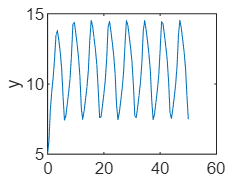

figure(1)
plot(x,y);
xlabel=('x');
ylabel('y');